# Lab 6 - Confidence Intervals

Thomas Conaway

clc; clear; close all;
lhcbg = makedist("Poisson","lambda",100);

## Problem 1

Determining the 5 sigma threshold.

fivesigma = icdf(lhcbg,1 - 3.5E-6)

fivesigma = 148

5 sigma sensitivity threshold is 148.

## Problem 2

TA: just add 190, is biased pending further review.

Injecting a single simulated signal. Let's say a signal of of 300, which is a little over 16 sigma.

abs(norminv(cdf(lhcbg,300,'upper')))

ans = 16.1463

Q: Not sure what injecting means. Will try using the method in the lecture slides.

size = 10000;
% noise = randn(1,size)*0.1;
% signal = zeros(1,size);
% signal(randi(numel(signal),[1,500])) = 2;
% obssignal = noise + signal;
% histogram(obssignal);
pnoise = poissrnd(100,[1,size]);
psignal = zeros(1,size);
psignal(randi(numel(psignal),[1,500])) = 300-0; % from 100 to 0, may need to rethink this, should strictly be normal?
pobssignal = pnoise + psignal;

**a)** Histogramming the observed signal:

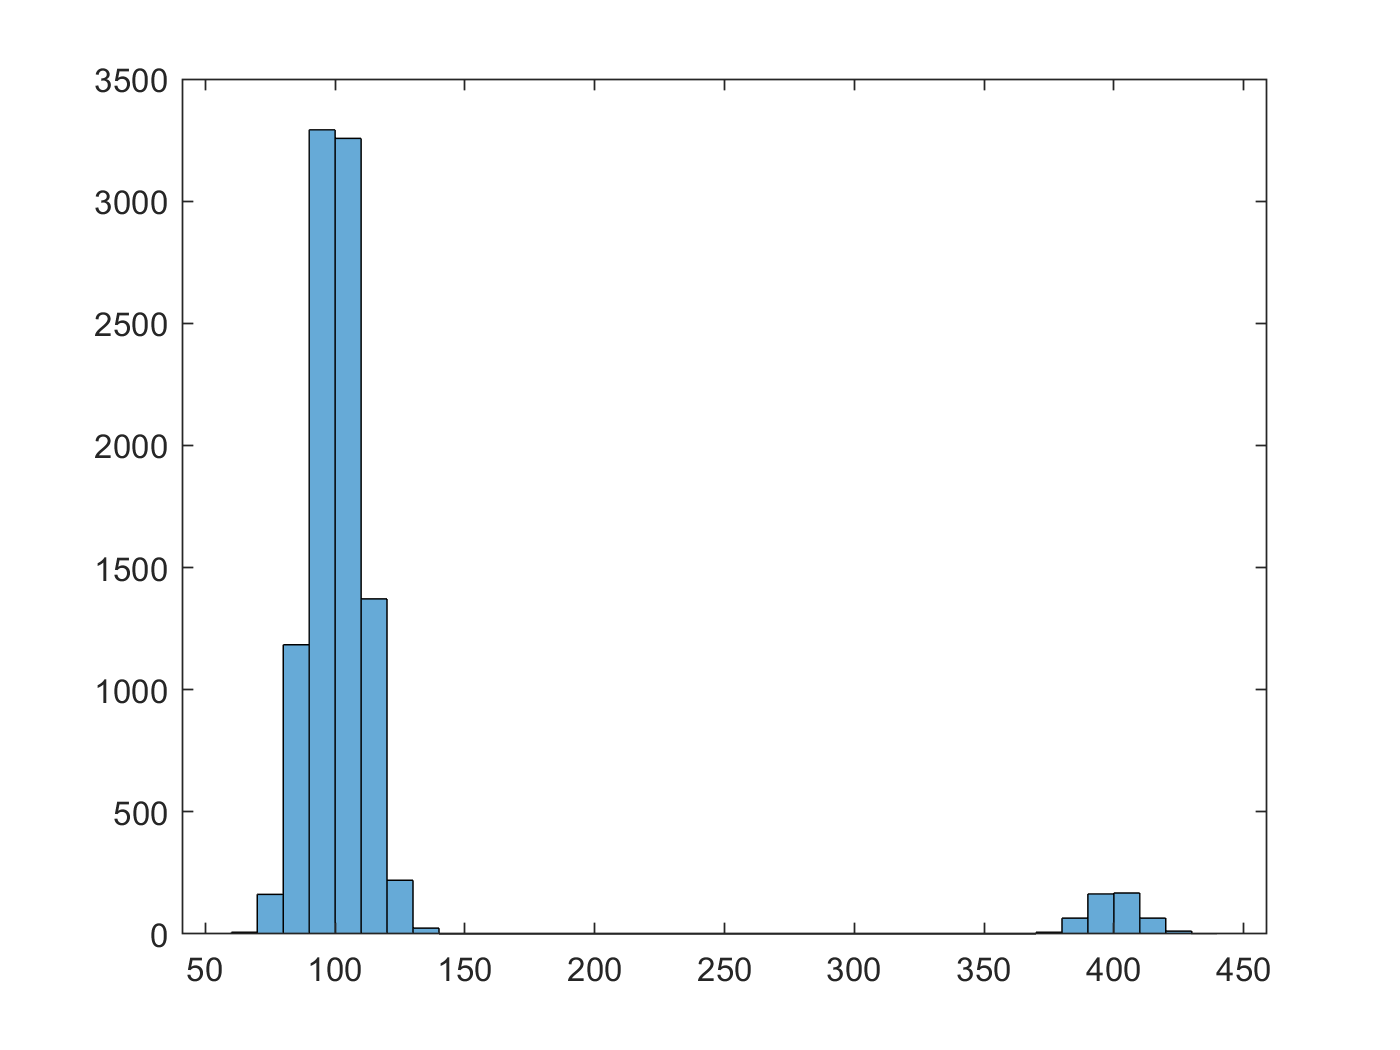

histogram(pobssignal);

% set(gca,'YScale','log');

Signal appears as the group of bins centered at 300. Shape appears to be Gaussian (setting the y-axis to a logscale shows the downward parabola). This histogram is telling us that the observed signal can take on a range of values, normally (poisson?) distributed around 300.

**b)** Signal does not appear to be biased, symmetric about 300, unless by signal we are including the background, in which case the measured value we get will far more likely be less than 300.

## Problem 3

Suite of injected signals (like in lecture 14):

signals = 100:1:500; % 500 gets a little over 28 sigma
% this is shaping the height of my problem histogram

a) We will now be simulating observed signals for a range of injected signals, plotted as a 2d histogram.

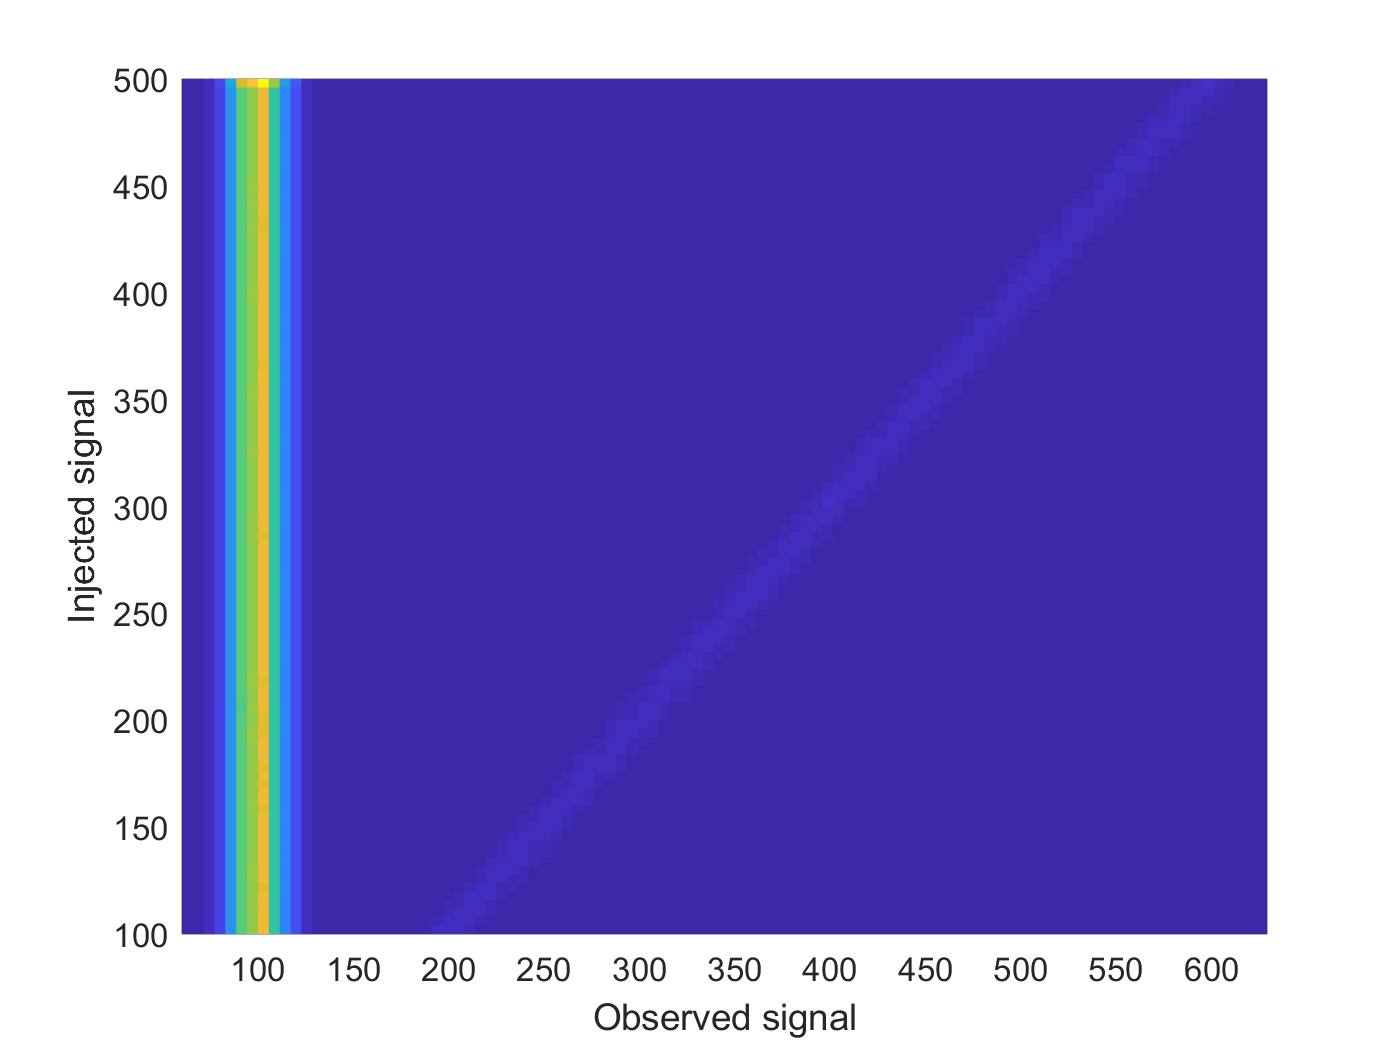

size = 10000;
% signals = linspace(100,500,size); % too large
pnoise = poissrnd(100,[1,size]);
psignals = zeros(numel(signals),size);%
pobssignals = zeros(numel(signals),size);
puresignals = zeros(numel(signals),size);
for k = 1:numel(signals)
    %psignals(:,k) = signals;%
    psignals(k,:) = signals(k);
    psignal = zeros(1,size);
    indices = randi(numel(psignal),[1,500]);%
    %psignal(randi(numel(psignal),[1,500])) = signals(k) - 100; % may need to rethink this, should strictly be normal?
    psignal(indices) = signals(k) - 0;%from 100 to 0
    pobssignals(k,:) = pnoise + psignal;
    puresignals(k,indices) = pobssignals(k,indices);
    %puresignals(k,:) = 
end
%[index, value] = find(puresignals);
puresignals(puresignals == 0) = nan;

histogram2(pobssignals,psignals,100,'DisplayStyle','tile','ShowEmptyBins','on');
% histogram2(psignals,pobssignals,100,'DisplayStyle','tile','ShowEmptyBins','on');
% my thoughts are: this isn't the correct way, the histogram is generating
% a point x,y from array element pairs and trying to histogram these.
% ylim([0,10]);
ylabel("Injected signal");
xlabel("Observed signal");

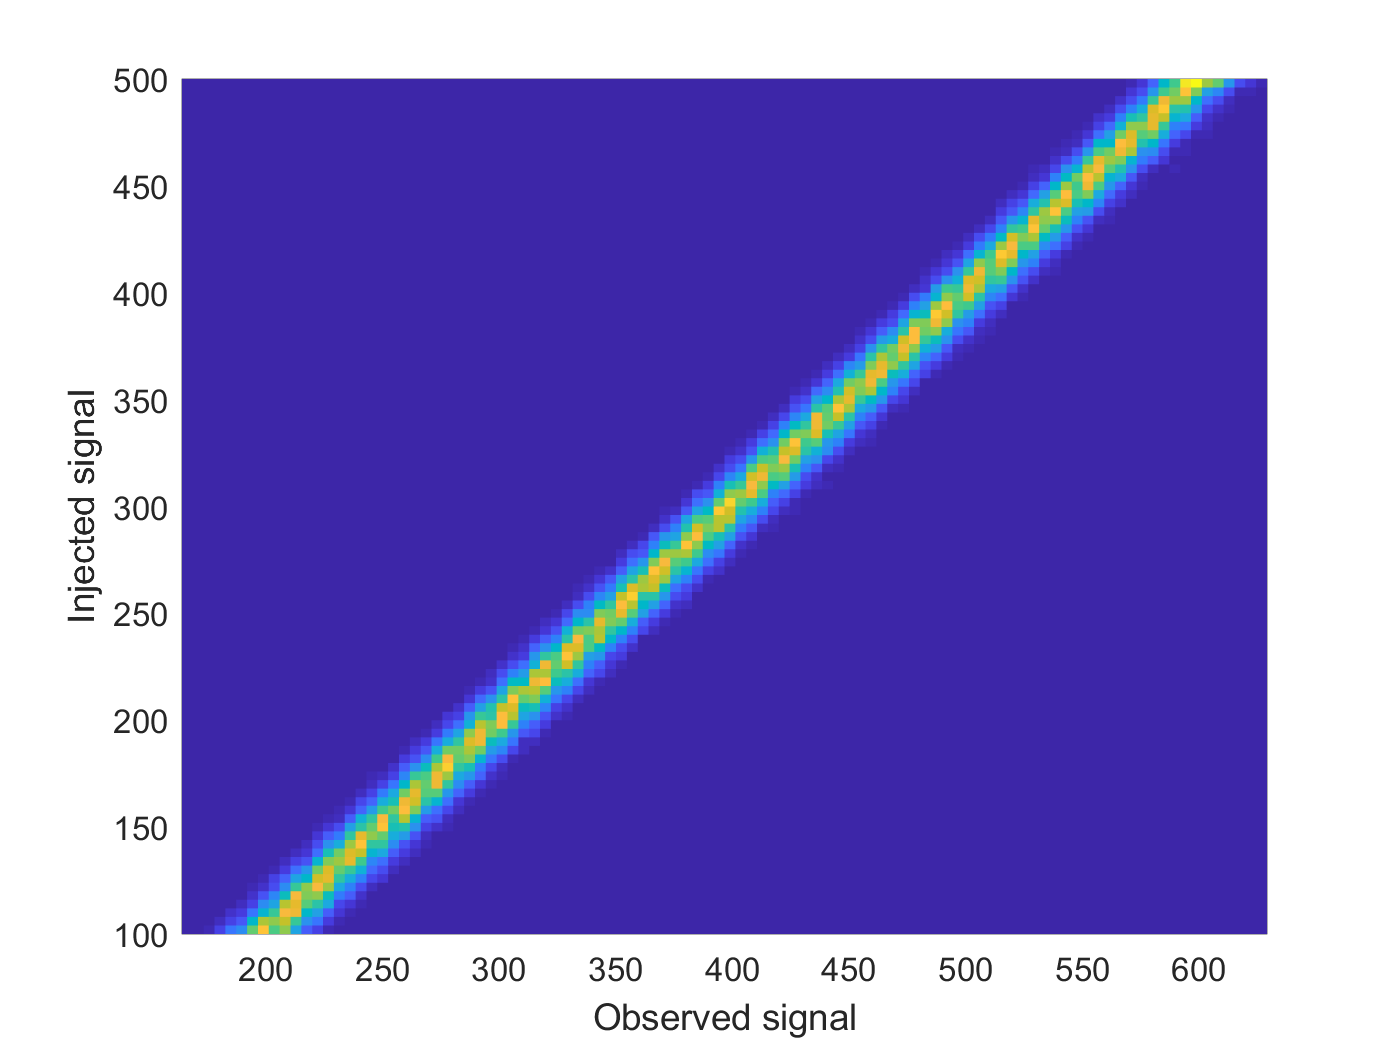

histogram2(puresignals,psignals,100,'DisplayStyle','tile','ShowEmptyBins','on');
ylabel("Injected signal");
xlabel("Observed signal");

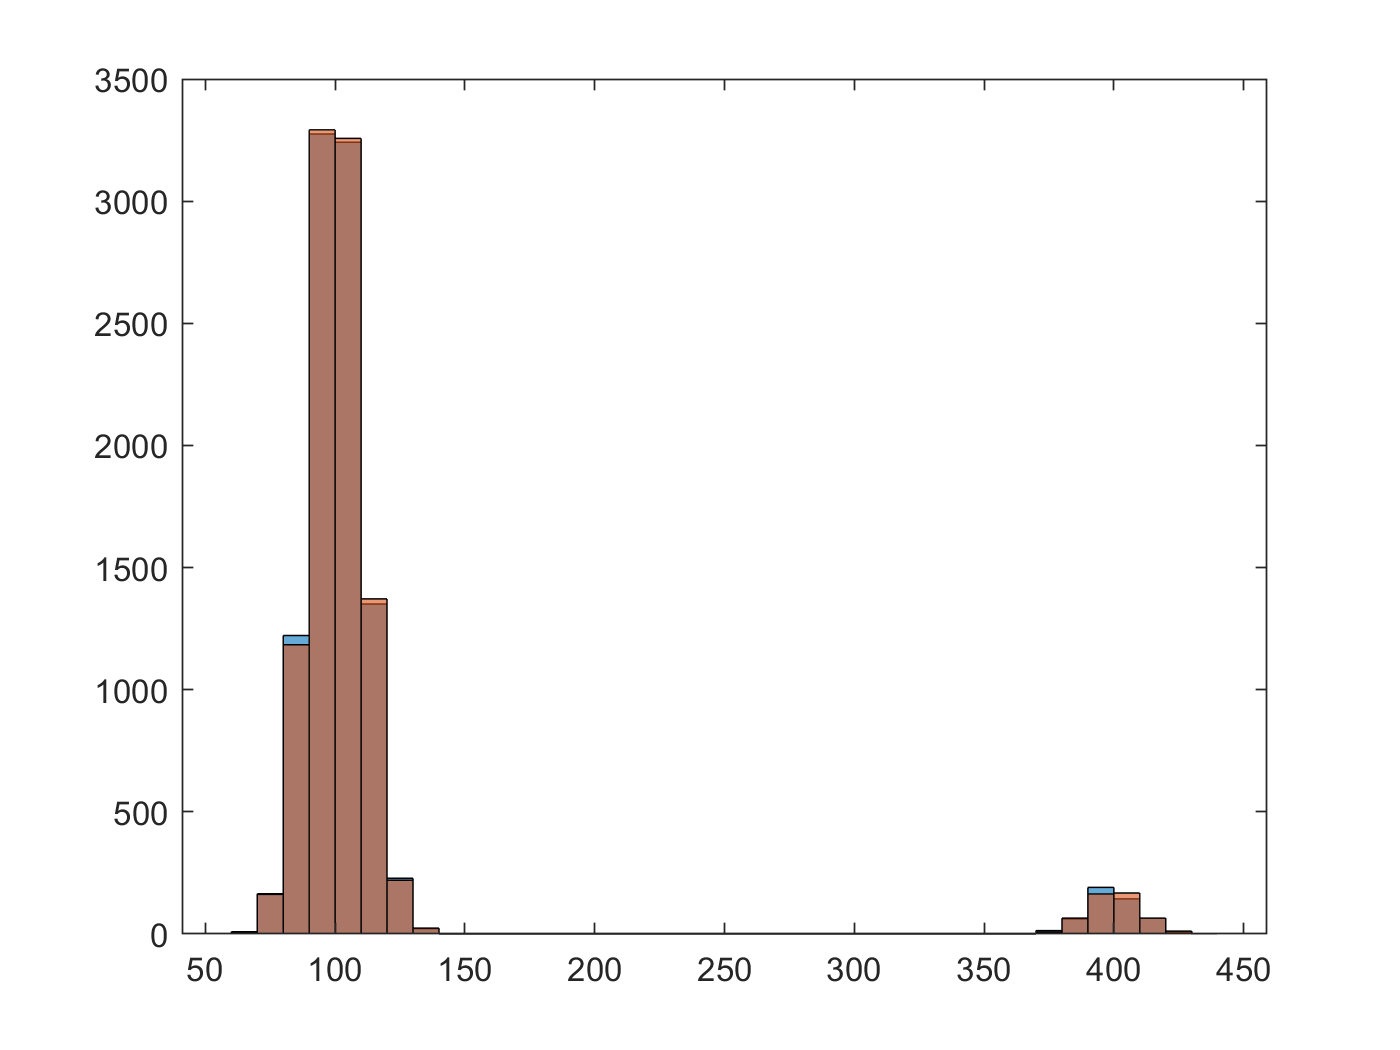

histogram(pobssignals(200,:)) % this looks right
hold on;
histogram(pobssignal);
hold off;

**b)** Looks good. The method I used for generating the suite produced a different random set of noise, but they still closely follow the original histogram for an injected signal of 300. 

**c)** Observed signal 300 vertical histogram:

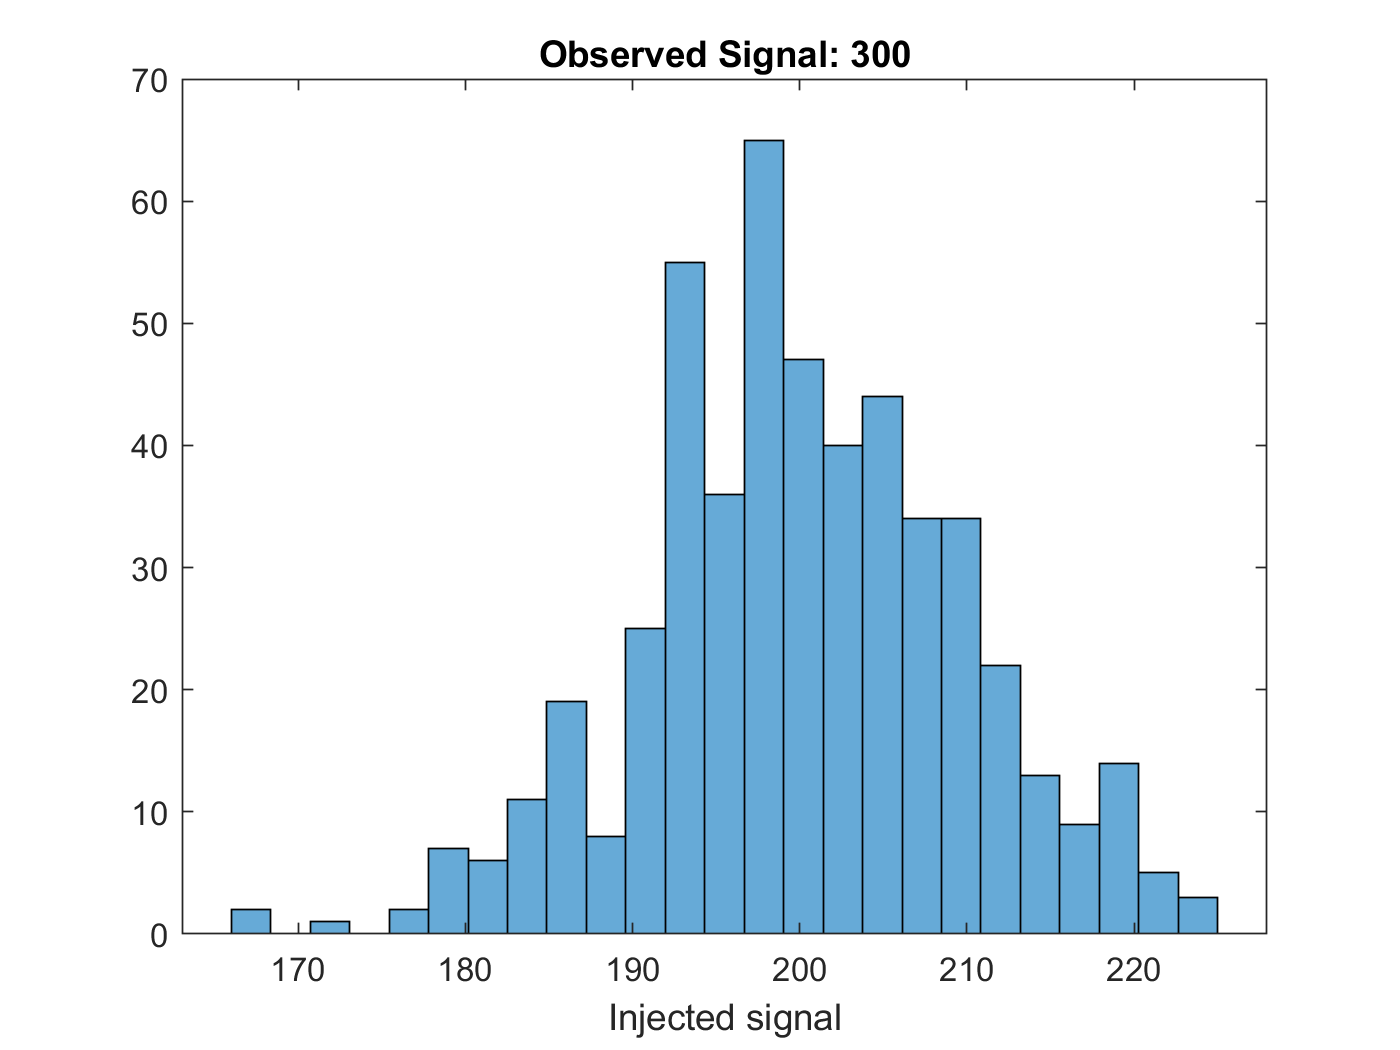

injected1 = psignals(abs(pobssignals - 300)<0.05);
histogram(injected1,25);
title("Observed Signal: 300");
xlabel("Injected signal");


injected2 = psignals(abs(puresignals - 300)<0.05);
histogram(injected2,25);
title("Observed Signal: 300");
xlabel("Injected signal");



%X = [0 1 2 1; 1 2 3 2; 2 3 4 10];
%Y = [4 1 2 1; 1 2 3 2; 2 3 4 11];
%histogram2(X,Y,'DisplayStyle','tile','ShowEmptyBins','on');

% size = 1000;
% noise = random('Lognormal',0.1,0.1,size,size);
% signalstrength = linspace(0.1,5,1000);
% [scratch, signal] = meshgrid(signalstrength);
% obssignal = noise + signal;
% figure()
% h = histogram2(obssignal,signal,100,'DisplayStyle','tile','ShowEmptyBins','on');
% histogram(obssignal(500,:)) % seems to also be working
% ylabel("Injected signal")
% xlabel("observed signal")
% title("Confidence intervals")
% xlim([0.8 6])


% noise = random('Poisson',100,size,size); % crazy big, don't run.